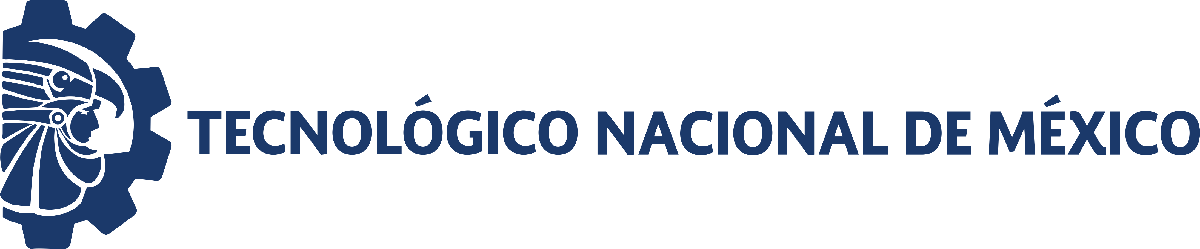                                 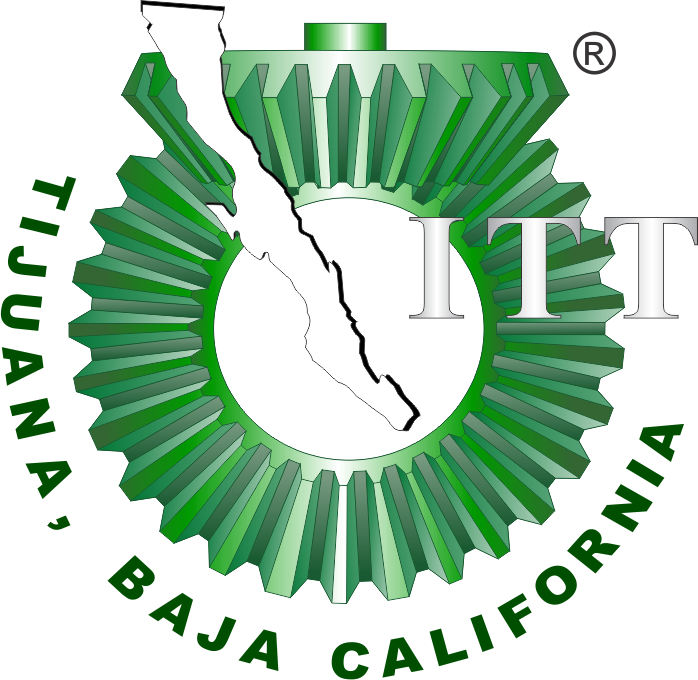

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: Maria Fernanda Almazan Pacheco 

Número de control: 22211744

Correo institucional: L22211744

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.stoptime = tend;
parameters.solver ='ode23t';
parameters.Maxstep = '1E-3';
% set_param('sitema/PA1(t)','vectorFormat','1-D array');

## Respuesta al escalón

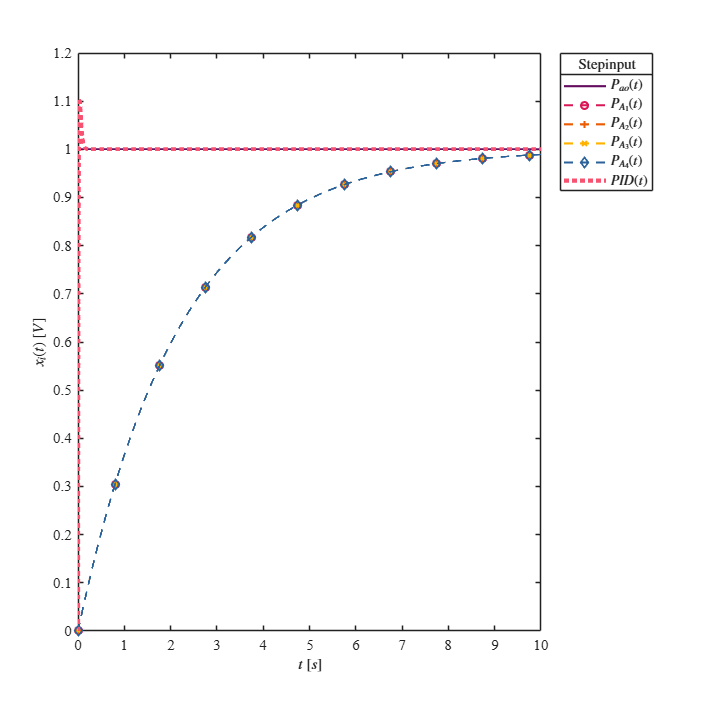

Signal = 'Step';
set_param('sistema/s1','sw','1');
set_param('sistema/pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.pao,x1.PA1, x1.PA2, x1.PA3, x1.PA4,x1.PID, Signal)

## Respuesta al impulso

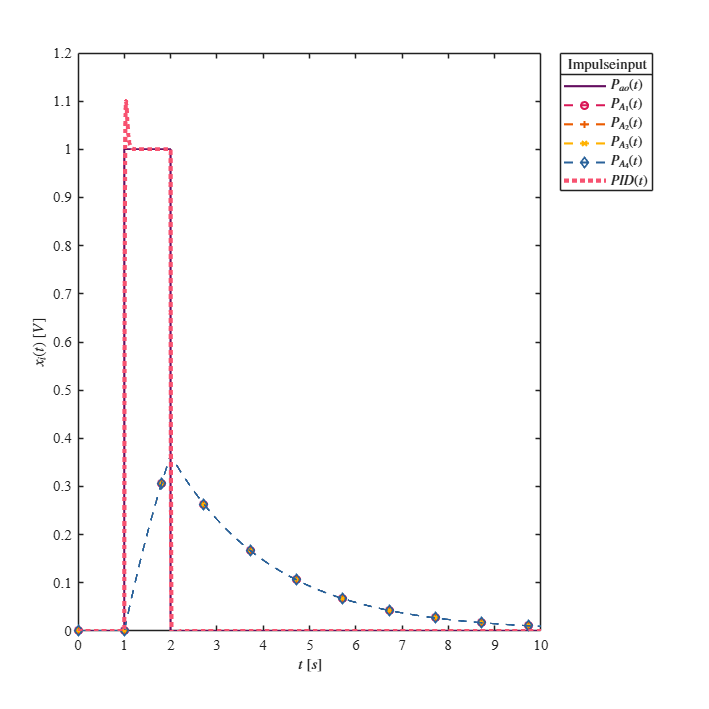

Signal = 'Impulse';
set_param('sistema/s1','sw','0');
set_param('sistema/pao(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.pao,x2.PA1, x2.PA2, x2.PA3, x2.PA4, x2.PID, Signal)

## Respuesta a la rampa

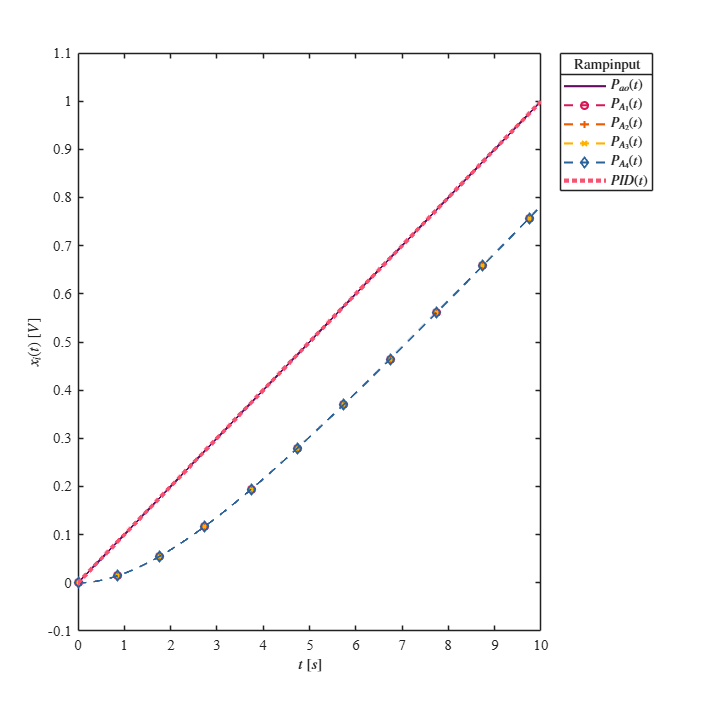

Signal = 'Ramp';
set_param('sistema/s2','sw','1');
set_param('sistema/pao(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.pao,x3.PA1,x3.PA2,x3.PA3,x3.PA4,x3.PID,Signal)

## Funcion: Respuesta a las señales 

function plotsignals(t,pao,PA1, PA2, PA3,PA4,PID, Signal)
set(figure(), 'Color', 'W')
set(gcf,'units','centimeters','position',[1,1,18,18])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors =  [100,13,95;
             217,22,86;
             235,91,0;
             255,178,0;
             42,98,154 
             247,82,112]/255;
    colororder(mycolors)

        
   p=(plot(t,pao,'-',t,PA1,'--O',t,PA2,'--+',t,PA3,'--X',t,PA4,'--d',t,PID,':',...
    'LineWidth', 1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t)));

    set(p(6),'LineWidth',3);
    L = legend('$P_{ao}(t)$', '$P_{A_1}(t)$','$P_{A_2}(t)$','$P_{A_3}(t)$','$P_{A_4}(t)$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal, 'input'], 'FontSize',11)

    xlabel('$t$ $[s]$','Interpreter','Latex','Fontsize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks (0:1:10);

    if Signal == "Step" || Signal== "Impulse"
        ylim([0,1.2]); yticks (0:0.1:1.2);
    elseif Signal  == "Ramp"
        ylim([-0.1,1.1]); yticks (-0.1:0.1:1.1);
    elseif Signal  == "Sin"
        ylim([-1.2,1.2]); yticks (-1.2:0.2:2);
    end
    exportgraphics (gcf,[Signal, '.pdf'],'ContentType','vector')
    exportgraphics (gcf,[Signal, '.png'],'ContentType','vector')
end          

## Respuesta a la función sinusoidal

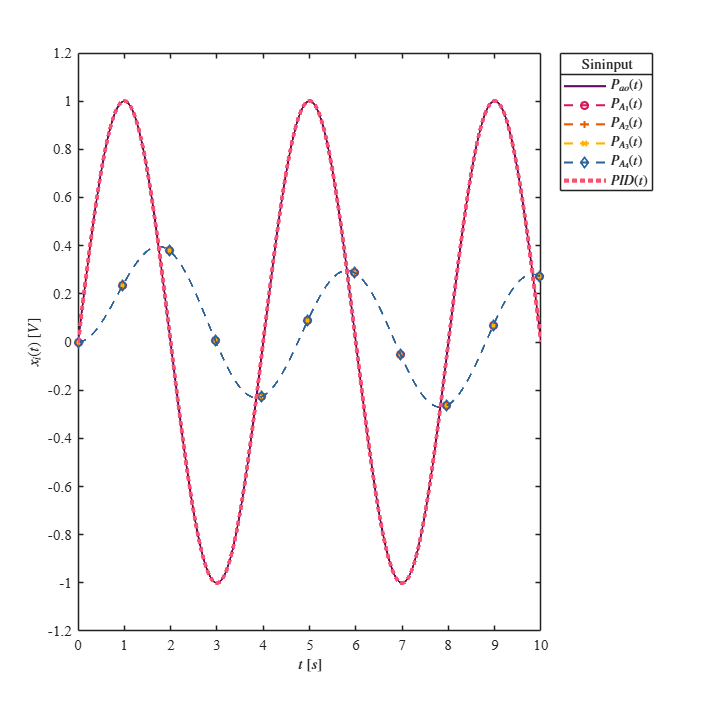

Signal = 'Sin';
set_param('sistema/s2','sw','0');
set_param('sistema/pao(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.pao,x4.PA1,x4.PA2,x4.PA3,x4.PA4,x4.PID,Signal)